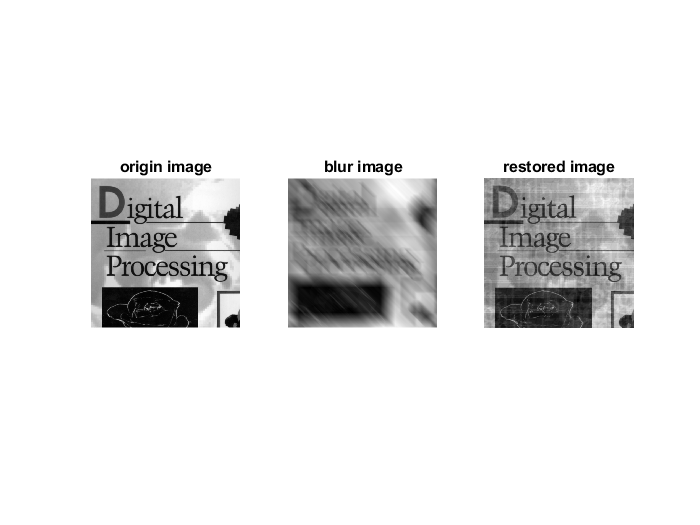

Im = imread('DIP.jpg');
F = fft2(Im);
Fc = fftshift(F);

row = size(Im,1);
col = size(Im,2);
a = -0.1;
b = -0.1;
T = 1;
[u, v] = meshgrid(-row/2:row/2-1, -col/2:col/2-1);
%u = u + 0.0001;
%v = v + 0.0001;
H = T./(pi*(u*a+v*b)+0.0001) .* sin(pi*(u*a+v*b)).*exp(-1i*pi*(u*a+v*b));

%imshow(H)
G = H.* Fc;
gi = ifft2(ifftshift(G));
g = real(gi);

%imshow(uint8(g))
% %F_in = G./H;
% im_re = G.*(H^-1);
% imshow(real(im_re))
% F_restore = fft2(fftshift(im_re));
% F_restore1 = ifft2(ifftshift(im_re));
% imshow(F_restore)
% imshow(F_restore1)
% %imshow(real(F_in));



G = fft2(g);
G_s= fftshift(G);
%imshow(H)
% G = (H^-1)./ Fc_resore;
Fc_resore = G_s./(H+0.0001);
g_re= real(ifft2(ifftshift(Fc_resore)));


figure,
subplot(1,3,1);
imshow(Im);title('origin image');
subplot(1,3,2);
imshow(g, []),title('blur image');
subplot(1,3,3);
%imshow(g_re);
imshow(g_re, []);title('restored image');

%doc immse
fprintf('\n The mean-squared error of blur image to origin is %0.4f\n', immse(uint8(g),Im))


 The mean-squared error of blur image to origin is 18058.2579


fprintf('\n The mean-squared error of blur image to origin is %0.4f\n', immse(uint8(g_re),Im))


 The mean-squared error of blur image to origin is 14098.4752


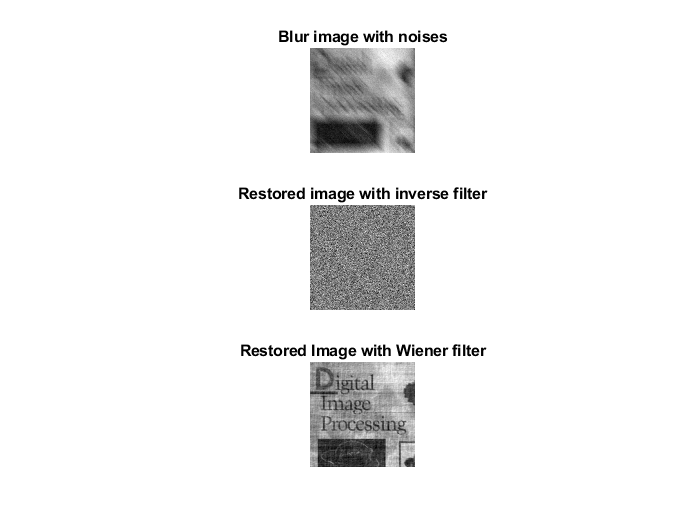

%doc randn
g_new = real(gi);
g_new =g_new+sqrt(50).*randn(size(g_new,1),size(g_new,2))+0;


%Apply simple inverse filter
G = fft2(g_new);
G_s= fftshift(G);
% G = (H^-1)./ Fc_resore;
Fc_resore = G_s./(H + 0.0001);
g_re_new= real(ifft2(ifftshift(Fc_resore)));



%Apply Wiener filter
g_f = fftshift(fft2(g_new));
Im_f = fftshift(fft2(Im));
SNR_in = (abs(g_f).^2)./(abs(Im_f).^2);
h2 = conj(H).*H;
Wi_fil1 = (1./(H+0.001)).*(h2./(h2+SNR_in));
G = fft2(g_new);
G_s= fftshift(G);
Fc_re_wine = G_s .*(Wi_fil1);
g_re_wine = real(ifft2(ifftshift(Fc_re_wine)));


figure,
subplot(3,1,1);
imshow(g_new, []),title('Blur image with noises');  
subplot(3,1,2);
imshow(g_re_new,[]),title('Restored image with inverse filter');
subplot(3,1,3);
imshow(g_re_wine,[]),title('Restored Image with Wiener filter');

## e. Explain

Since we have taken real part when using normal filter and add some noise to the blur image.

Thus when we restore using the inverse filter some information will be lost.

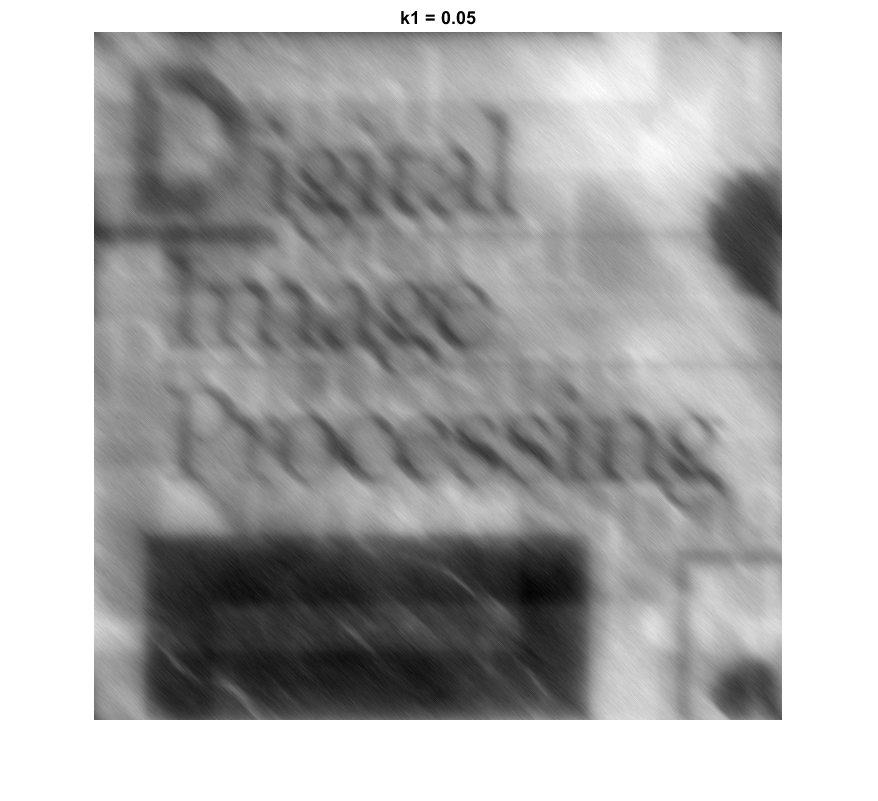

k1 = 0.05;
k2 = 0.005;
k3 = 1.5;

g_f = fftshift(fft2(g_new));
Im_f = fftshift(fft2(Im));
h2 = conj(H).*H;
Wi_fil1 = (1./(H+0.001)).*(h2./(h2+k1));
G = fft2(g_new);
G_s= fftshift(G);
Fc_re_wine = G_s .*(Wi_fil1);
g_re_wine_1 = real(ifft2(ifftshift(Fc_re_wine)));
figure,imshow(g_re_wine_1,[]),title('k1 = 0.05')

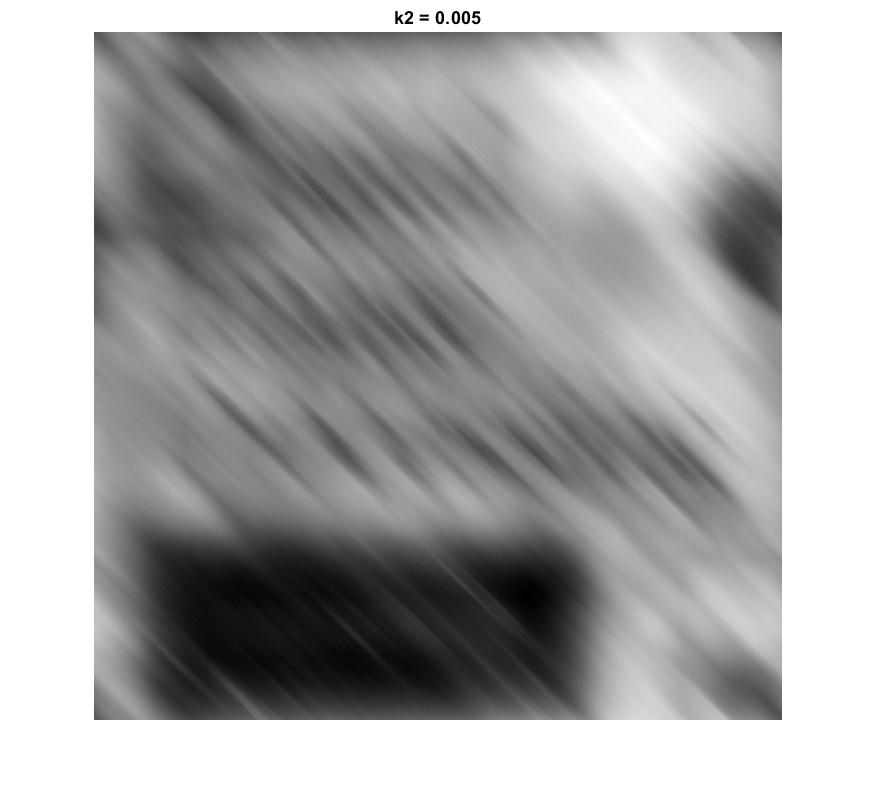

% g_f = fftshift(fft2(g_new));
% Im_f = fftshift(fft2(Im));
h2 = conj(H).*H;
Wi_fil1 = (1./(H+0.001)).*(h2./(h2+k2));
G = fft2(g_new);
G_s= fftshift(G);
Fc_re_wine = G_s .*(Wi_fil1);
g_re_wine_2 = real(ifft2(ifftshift(Fc_re_wine)));
figure,imshow(g_re_wine_2,[]),title('k2 = 0.005')

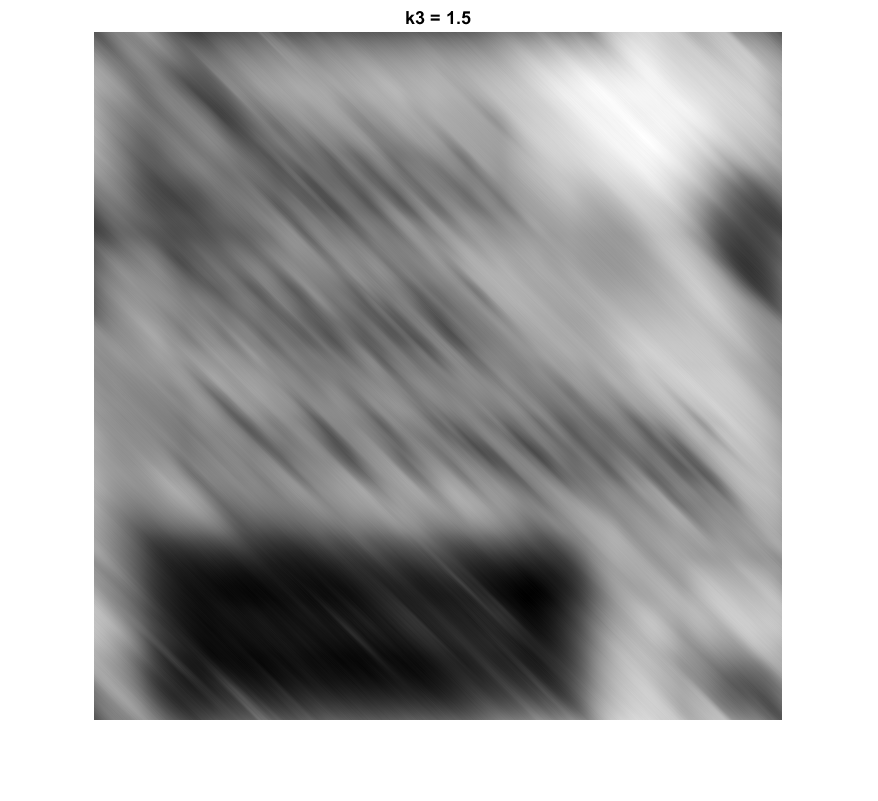

% g_f = fftshift(fft2(g_new));
% Im_f = fftshift(fft2(Im));
h2 = conj(H).*H;
Wi_fil1 = (1./(H+0.001)).*(h2./(h2+k2));
G = fft2(g_new);
G_s= fftshift(G);
Fc_re_wine = G_s .*(Wi_fil1);
g_re_wine_3 = real(ifft2(ifftshift(Fc_re_wine)));
figure,imshow(g_re_wine_3,[]),title('k3 = 1.5')